## Initial Runge-Kutta 4 method

Implementation with adaptive step.

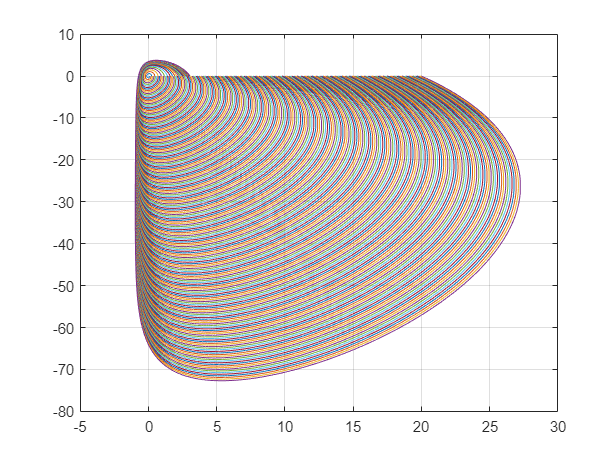

% a1=1;b1=1;c1=0;al1=0;bt1=1;
% a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;

tmax=4;

% Starting values of x
values=setdiff(0.1:0.1:20,0);

x2=zeros(size(values));
T=zeros(size(values));
xdif=zeros(size(values));

for i=1:size(values,2)
    x=[]; x(1) = values(i);
    y=[]; y(1) = 0;
    [x,y,T(i)] = RK4c(x,y,tmax,a2,b2,c2,al2,bt2);
    x2(i)=values(i);
    xdif(i)=x(end)-x(1);
    plot(x,y);
    hold on
end
grid on
hold off

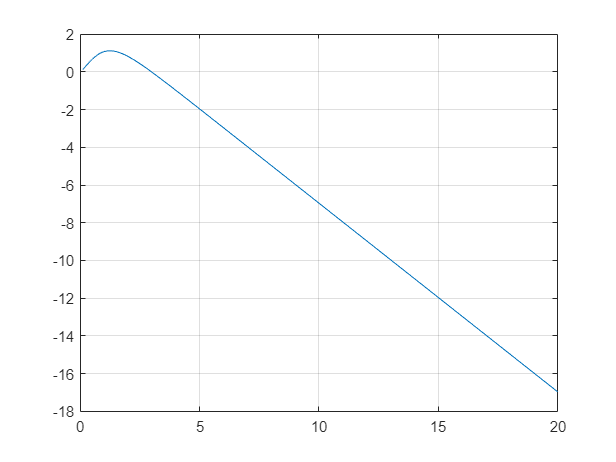

plot(x2,xdif);
grid on

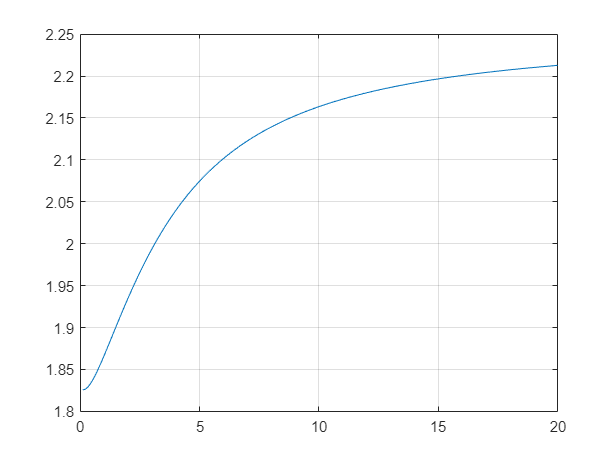

plot(x2,T);
grid on

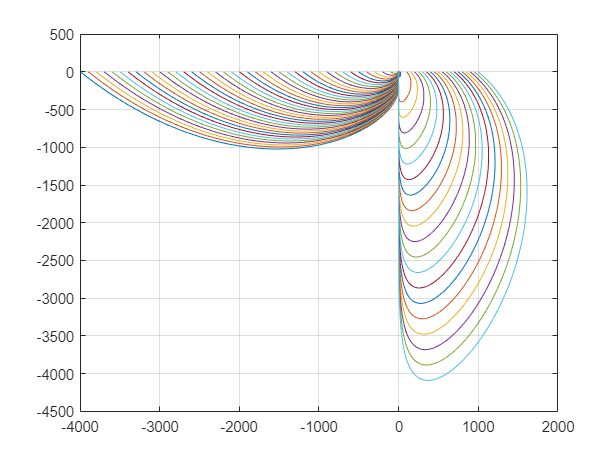

tmax=5;

% Starting values of x
values=setdiff([-4000:100:-100,-20:1:-1,0.1:0.1:99,100:50:1000],0);

x2=zeros(size(values));
T=zeros(size(values));
xdif=zeros(size(values));

for i=1:size(values,2)
    x=[]; x(1) = values(i);
    y=[]; y(1) = 0;
    [x,y,T(i)] = RK4c(x,y,tmax,a2,b2,c2,al2,bt2);
    x2(i)=values(i);
    xdif(i)=x(end)-x(1);
    plot(x,y);
    hold on
end
grid on
hold off

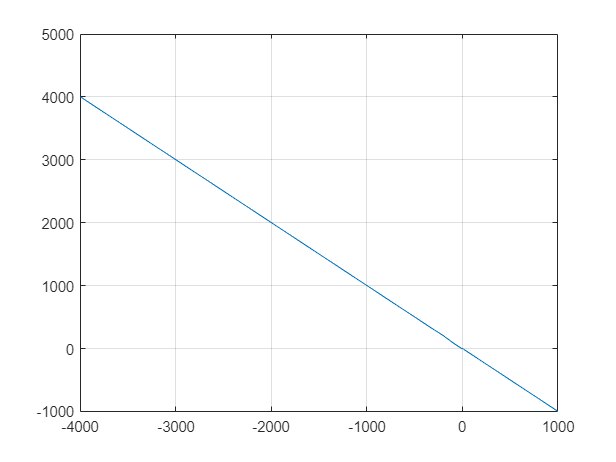

plot(x2,xdif);
grid on

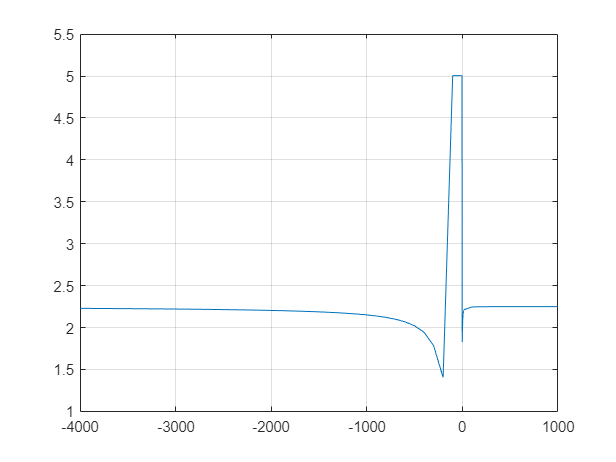

plot(x2,T);
grid on

Large negative limit cycle not found with increasing time (distance gets larger). Attempt with decreasing time:

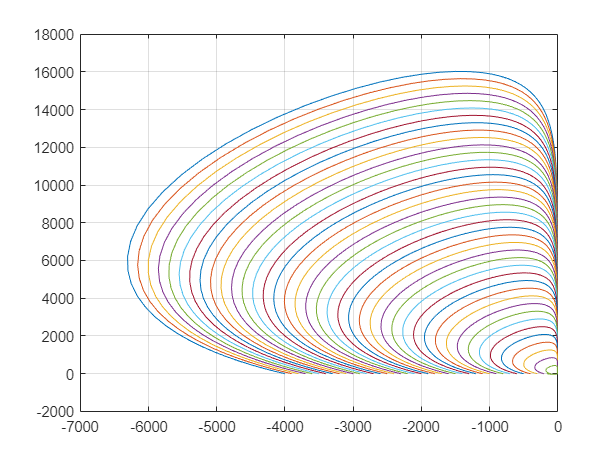

tmaxR=-20;

valuesR=setdiff(-4000:100:0,0);

x2R=zeros(size(valuesR));
TR=zeros(size(valuesR));
xdifR=zeros(size(valuesR));

for i=1:size(valuesR,2)
    xR=[]; xR(1) = valuesR(i);
    yR=[]; yR(1) = 0;
    [xR,yR,TR(i)] = RK4rev(xR,yR,tmaxR,a2,b2,c2,al2,bt2);
    x2R(i)=valuesR(i);
    xdifR(i)=xR(end)-xR(1);
    plot(xR,yR);
    hold on
end
grid on
hold off

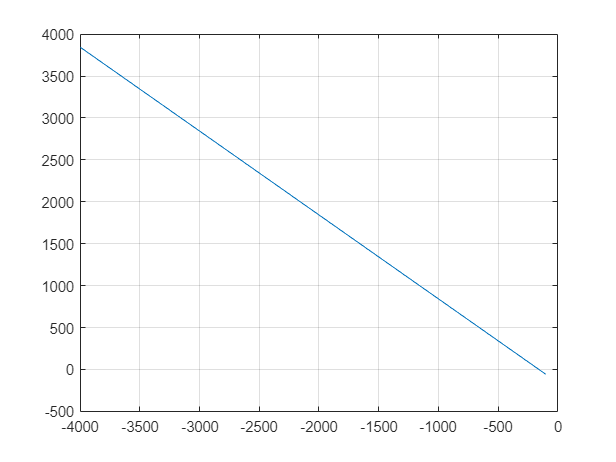

plot(x2R,xdifR);
grid on

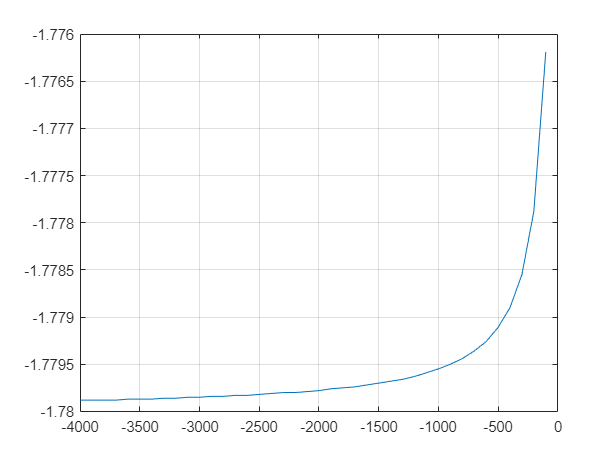

plot(x2R,TR);
grid on

## Functions

function [x,y,T] = RK4c(x,y,tmax,a2,b2,c2,al2,bt2)
    
    % ODE
    a1=1;b1=1;c1=0;al1=0;bt1=1;
    dxdt=@(x,y) a1*x^2 + b1*x*y + c1*y^2 + al1*x + bt1*y;
    dydt=@(x,y) a2*x^2 + b2*x*y + c2*y^2 + al2*x + bt2*y;
    
    % Runge-Kutta 4
    
    tprev=0.01;
    epsilon=0.01;
%     dt = 0.001;
%     dt1=@(x,y) min(0.01,epsilon/(dxdt(x,y)^2+dydt(x,y)^2));
    dt1=@(x,y) max(0.00001,min(0.01,epsilon/(dxdt(x,y)^2+dydt(x,y)^2)));
%     dt2=@(x,y) epsilon/(dxdt(x,y)^2+dydt(x,y)^2);

        for i=1:1:2

            dt = dt1(x(i), y(i));

            k1x=dxdt(x(i), y(i));
            k1y=dydt(x(i), y(i));
        
            k2x=dxdt(x(i)+dt/2*k1x, y(i)+dt/2*k1y);
            k2y=dxdt(x(i)+dt/2*k1x, y(i)+dt/2*k1y);
        
            k3x=dxdt(x(i)+dt/2*k2x, y(i)+dt/2*k2y);
            k3y=dxdt(x(i)+dt/2*k2x, y(i)+dt/2*k2y);
        
            k4x=dxdt(x(i)+dt*k3x, y(i)+dt*k3y);
            k4y=dxdt(x(i)+dt*k3x, y(i)+dt*k3y);
        
            x(i+1)=x(i) + dt/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + dt/6*(k1y+2*k2y+2*k3y+k4y);
            
            tprev=tprev+dt;
        
        end

        i=3;
        sign_change=0;

        while sign_change<2 && tprev<tmax

            dt = dt1(x(i), y(i));

            k1x=dxdt(x(i), y(i));
            k1y=dydt(x(i), y(i));
        
            k2x=dxdt(x(i)+dt/2*k1x, y(i)+dt/2*k1y);
            k2y=dxdt(x(i)+dt/2*k1x, y(i)+dt/2*k1y);
        
            k3x=dxdt(x(i)+dt/2*k2x, y(i)+dt/2*k2y);
            k3y=dxdt(x(i)+dt/2*k2x, y(i)+dt/2*k2y);
        
            k4x=dxdt(x(i)+dt*k3x, y(i)+dt*k3y);
            k4y=dxdt(x(i)+dt*k3x, y(i)+dt*k3y);
        
            x(i+1)=x(i) + dt/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + dt/6*(k1y+2*k2y+2*k3y+k4y);
            
            tprev=tprev+dt;
            i=i+1;

            if y(i)*y(i-1)<0
                sign_change=sign_change+1;
            end

        end
        
        T=tprev;
end

function [x,y,T] = RK4rev(x,y,tmax,a2,b2,c2,al2,bt2)
    
    % ODE
    a1=1;b1=1;c1=0;al1=0;bt1=1;
    dxdt=@(x,y) a1*x^2 + b1*x*y + c1*y^2 + al1*x + bt1*y;
    dydt=@(x,y) a2*x^2 + b2*x*y + c2*y^2 + al2*x + bt2*y;
    
    % Runge-Kutta 4
    
    tprev=0.01;
    epsilon=-0.01;
%     dt = 0.001;
%     dt1=@(x,y) min(0.01,epsilon/(dxdt(x,y)^2+dydt(x,y)^2));
    dt1=@(x,y) min(-0.00001,max(-0.01,epsilon/(dxdt(x,y)^2+dydt(x,y)^2)));
%     dt2=@(x,y) epsilon/(dxdt(x,y)^2+dydt(x,y)^2);

        for i=1:1:2

            dt = dt1(x(i), y(i));

            k1x=dxdt(x(i), y(i));
            k1y=dydt(x(i), y(i));
        
            k2x=dxdt(x(i)+dt/2*k1x, y(i)+dt/2*k1y);
            k2y=dxdt(x(i)+dt/2*k1x, y(i)+dt/2*k1y);
        
            k3x=dxdt(x(i)+dt/2*k2x, y(i)+dt/2*k2y);
            k3y=dxdt(x(i)+dt/2*k2x, y(i)+dt/2*k2y);
        
            k4x=dxdt(x(i)+dt*k3x, y(i)+dt*k3y);
            k4y=dxdt(x(i)+dt*k3x, y(i)+dt*k3y);
        
            x(i+1)=x(i) + dt/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + dt/6*(k1y+2*k2y+2*k3y+k4y);
            
            tprev=tprev+dt;
        
        end

        i=3;
        sign_change=0;

        while sign_change<2 && tprev>tmax

            dt = dt1(x(i), y(i));

            k1x=dxdt(x(i), y(i));
            k1y=dydt(x(i), y(i));
        
            k2x=dxdt(x(i)+dt/2*k1x, y(i)+dt/2*k1y);
            k2y=dxdt(x(i)+dt/2*k1x, y(i)+dt/2*k1y);
        
            k3x=dxdt(x(i)+dt/2*k2x, y(i)+dt/2*k2y);
            k3y=dxdt(x(i)+dt/2*k2x, y(i)+dt/2*k2y);
        
            k4x=dxdt(x(i)+dt*k3x, y(i)+dt*k3y);
            k4y=dxdt(x(i)+dt*k3x, y(i)+dt*k3y);
        
            x(i+1)=x(i) + dt/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + dt/6*(k1y+2*k2y+2*k3y+k4y);
            
            tprev=tprev+dt;
            i=i+1;

            if y(i)*y(i-1)<0
                sign_change=sign_change+1;
            end

        end
        
        T=tprev;
end